# ** Vision Artificial. GIEC, GITT.**

# **	Sistemas de Vision Artificial. GII, GISI, GIC.**

**	Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá.**

# Tema 5: Clasificadores (Supervised Learning)

**Nota**. Se necesita tener instalada la toolbox `"Statistics and Machine Learning"`

El objetivo de este ejercicio es entrenar clasificadores utilizando la base de datos  `hospital.mat `de Matlab, que contine datos simulados de 100 pacientes. Además se van a calcular las principales métricas para evaluar el funcionamiento de los clasificadores estudiados.

## k-Nearest Neighbour (kNN)

El clasificador que se va a estudiar es el k vecinos más próximos ([fitcknn](https://www.mathworks.com/help/stats/fitcknn.html)). 

**Se pide:**

- Selecciona de la base de datos `hospital` los datos correspondientes a la presión snaguinea (`BloodPressure``) y guardalos en ``data``.`

- Como etiquetas se va a utilizar si el paciente es fumado o no, el campo `Smoker` de la base de datos `hospital`. Como Smoker está codificado como [1 0] se debe pasar a categorías con la función [`categorical`](https://es.mathworks.com/help/matlab/ref/categorical.html), de tal modo que el valor `1` se corresponda con la etiqueta` 'Smoker' `y el valor `0` con la etiqueta `'Non-Smoker'`. el valor devuelto por categorical se guarda en `labels`.

- Finalmente se debe dividir la base de datos `hospital` en dos grupos: 70% para entrenamiento (`train_partition=0.7`) y 30% para test, utilizando la función [`cvpartition`](https://es.mathworks.com/help/stats/cvpartition.html) utilizando la opción `HoldOut`.

Finalmente se visualizan los datos usando un gráfico de dispersión.

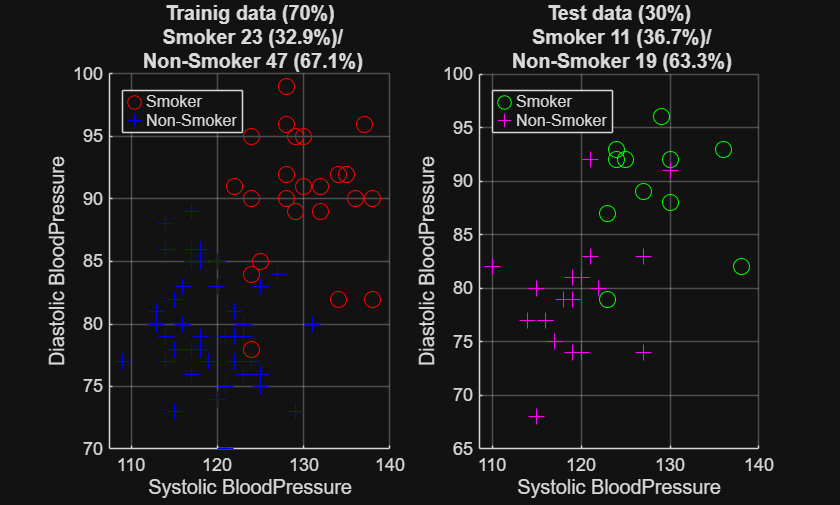

clear all;
close all;

% --- (1) ---
% Base de datos hospital 
load hospital;

rng(5)

% se utiuliza solo la presión sanguinea (BloodPressure)
data = hospital.BloodPressure;  
fumador = hospital.Smoker; % está en logical, la quiero en labels
labels = categorical(double(fumador), [1 0], {'Smoker' 'Non-Smoker'}); 


% 70% para entrenamiento y 
train_partition = 0.7;
% 30% para test
test_partition = 1 - train_partition;

%En HoldOut se pone el porcentaje que va a test (0.3), no el de entrenamiento.
cv = cvpartition(labels, 'HoldOut', test_partition);

% datos para entrenamiento
data_train = data(cv.training,:);
label_train = labels(cv.training);
tbl_train = tabulate(label_train);


% datos para test
data_test = data(cv.test, :);
label_test = labels(cv.test);
%crea una tabla de frecuencias que cuenta cuántas veces aparece cada valor único en un arreglo y calcula su porcentaje. 
%Se utiliza para verificar cómo quedaron repartidas las clases
tbl_test = tabulate(label_test);

% plot de los datos de entrenamiento y test
figure
subplot(1,2,1);
gscatter(data_train(:,1),data_train(:,2), label_train,'rb','o+',8,'on')
xlabel('Systolic BloodPressure');
ylabel('Diastolic BloodPressure');
legend('Location','northwest');
title(sprintf('Trainig data (%.0f%%)\n %s %d (%.1f%%)/\n %s %d (%.1f%%)'...
    ,train_partition*100, tbl_train{1,1}, tbl_train{1,2}, tbl_train{1,3}, tbl_train{2,1}, tbl_train{2,2}, tbl_train{2,3}));
grid on;
subplot(1,2,2);
gscatter(data_test(:,1),data_test(:,2), label_test,'gm','o+',8,'on')
xlabel('Systolic BloodPressure');
ylabel('Diastolic BloodPressure');
legend('Location','northwest');
title(sprintf('Test data (%.0f%%)\n %s %d (%.1f%%)/\n %s %d (%.1f%%)'...
    ,test_partition*100, tbl_test{1,1}, tbl_test{1,2}, tbl_test{1,3}, tbl_test{2,1}, tbl_test{2,2}, tbl_test{2,3}));
grid on;

**Se pide:**

- Complete con 4 valores  `k` (por ejemplo, `K = 1, 5, 10, 15`) del clasificador kNN.

- Complete los parámetros de la función [fitcknn](https://es.mathworks.com/help/stats/fitcknn.html), que obtiene el modelo del clasificador kNN.

Finalmente se visualizan las superficies de decisión. 

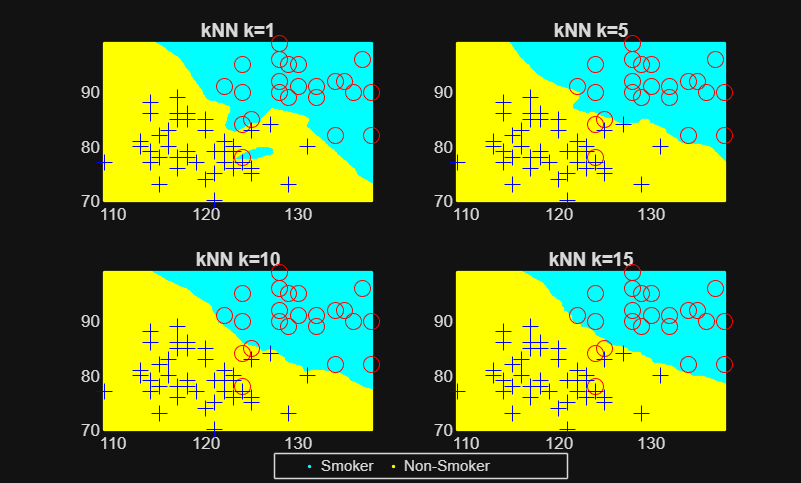

% --- (2) ---
fig = figure;

% máximo 4 valores de k
k = [1 5 10 15]; 

nModelos = numel(k);

% Preasignación de los modelos
% Arreglo de celdas (cell array) vacío preasignado para almacenar varios
% modelos de k-NN, uno por cada valor distinto de k
Model_kNN = cell(1,nModelos);   

% Preasignación de los nombres de los modelos
classifier_name = cell(1,nModelos); 

for i = 1:nModelos

    % Entrenamiento
    Model_kNN{i} = fitcknn(data_train, label_train, 'NumNeighbors', k(i));
    classifier_name{i} = sprintf('kNN k=%d', k(i));

    % visualización superficies de decisión 
    subplot(2,2,i);

    % El fondo de colores (cian y amarillo): es el "mapa" del clasificador. 
    % Muestra qué zonas considera de fumadores y cuáles de no fumadores
    plot_decision_surface(fig, Model_kNN{i}, data_train, 0.1, 'cy')
    hold on;

    %Encima, los pacientes reales de entrenamiento: círculos rojos (o) para Smoker y cruces azules (+) para Non-Smoker.
    gscatter(data_train(:,1),data_train(:,2), label_train,'rb','o+',8,'on')

    title(classifier_name{i})
    legend off, 
    axis tight
    hold off;
end
legend({'Smoker' 'Non-Smoker'},'Location',[0.35,0.01,0.35,0.05],'Orientation','Horizontal')

**Se pide:**

- Complete los parámetros de las funciones [predict](https://es.mathworks.com/help/stats/linearmodel.predict.html) y [confusionchart](https://es.mathworks.com/help/stats/confusionchart.html?s_tid=srchtitle_support_results_1_confusionchart) para evaluar los clasificadores kNN con los **datos de test**.

- Complete la función '`scores_binary_cm()`'  para calcular los parámetros: `Recall`, `Precision`, `F1_score`, y  `Accuracy `a partir de la matriz de confusión considerando como clase positiva (`P`) los fumadores (`'Smoker'`). 

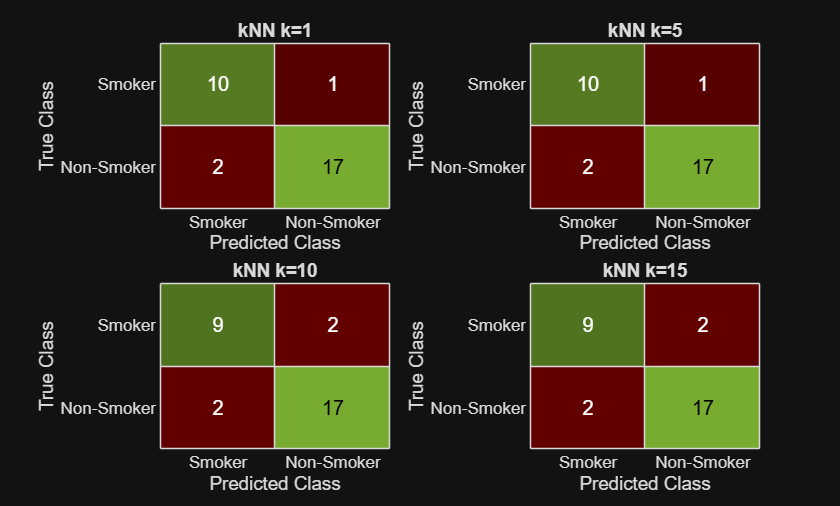

% --- (3) ---

% Se obtiene la predicción de los valores de Test
CM = zeros(2,2,numel(k));
kNN_scores = zeros(numel(k),4);

fig = figure;
for i = 1:numel(k)

    predictions_kNN = predict(Model_kNN{i}, data_test);

    subplot(2,2,i);
    cm = confusionchart(label_test, predictions_kNN, 'DiagonalColor', [0.4660 0.6740 0.1880], 'OffDiagonalColor','red');
    title(classifier_name{i})

    %% ===> ir a la función 'scores_binary_cm'
    kNN_scores(i,:) = scores_binary_cm(cm.NormalizedValues);
        
end

T_scores = array2table(kNN_scores,'RowNames', classifier_name,'VariableNames',{'Recall','Precision', 'F1_score','Accuracy'})

T_scores = 4×4 table
                Recall     Precision    F1_score    Accuracy
                _______    _________    ________    ________

    kNN k=1     0.90909     0.83333     0.86957         0.9 
    kNN k=5     0.90909     0.83333     0.86957         0.9 
    kNN k=10    0.81818     0.81818     0.81818     0.86667 
    kNN k=15    0.81818     0.81818     0.81818     0.86667 

	Get insights using Copilot


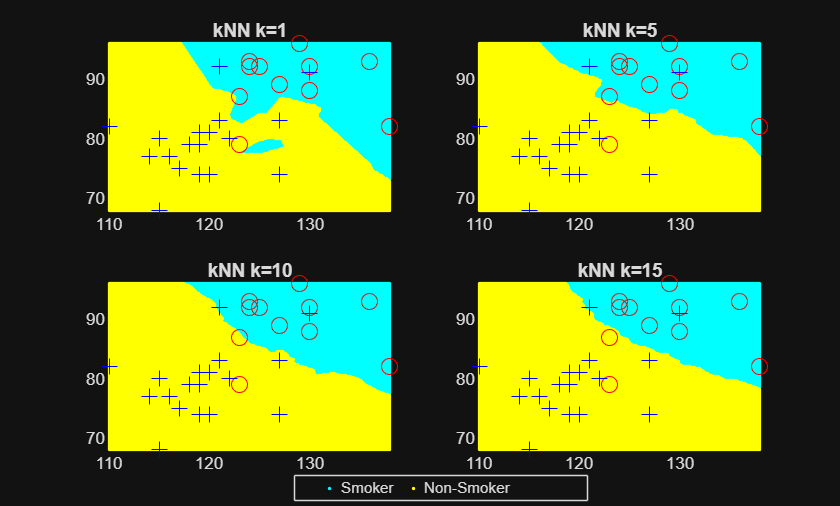


fig2 = figure;
for i = 1:numel(k)
% visualización superficies de decisión 
subplot(2,2,i);

% El fondo de colores (cian y amarillo): es el "mapa" del clasificador. 
% Muestra qué zonas considera de fumadores y cuáles de no fumadores
plot_decision_surface(fig2, Model_kNN{i}, data_test, 0.1, 'cy')
hold on;

%Encima, los pacientes reales de test: círculos rojos (o) para Smoker y cruces azules (+) para Non-Smoker.
gscatter(data_test(:,1),data_test(:,2), label_test,'rb','o+',8,'on')

title(classifier_name{i})
legend off, 
axis tight
legend({'Smoker' 'Non-Smoker'},'Location',[0.35,0.01,0.35,0.05],'Orientation','Horizontal')
hold off;
end

**Se pide:**

- Compare varios clasificadores utilizando la **APP** [*Clasification Learner*](https://es.mathworks.com/help/stats/train-classification-models-in-classification-learner-app.html#responsive_offcanvas) dentro de *Machine Learning and Deep Learning. *Para abrir Clasificator Learner, en la pestaña **Apps**, en **Machine Learning and Deep Learning**, haga clic en el icono de la app. Como alternativa, puede abrir la app desde la línea de comandos:

`clasificationLearner`

Sigua los siguientes pasos:

- Cargue una nueva sesión y elija seleccionar los datos desde el workspace, tal y como se muestra en la siguiente imagen.

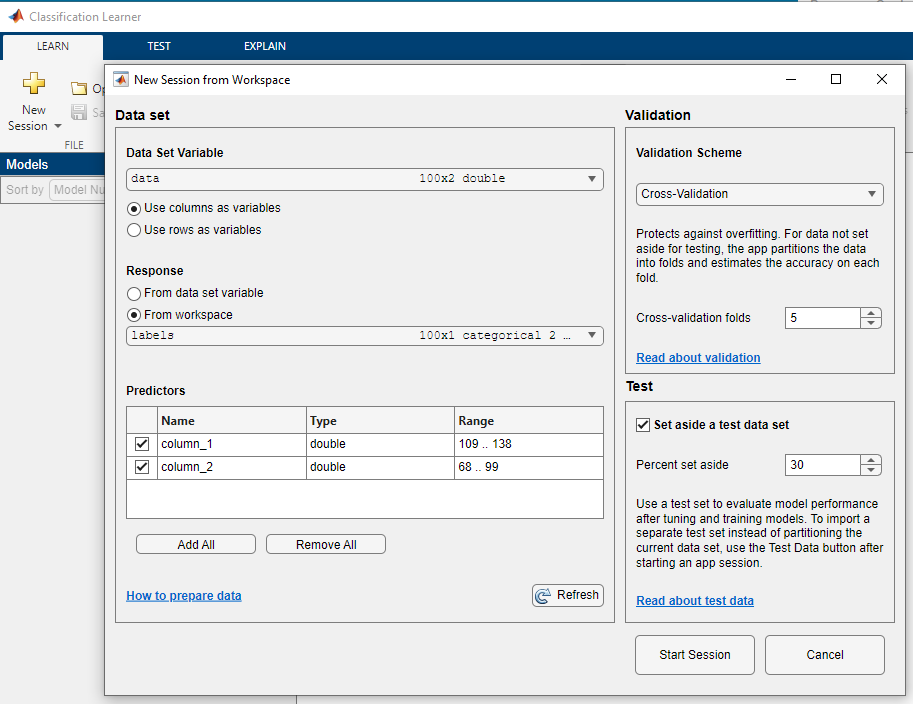

- Seleccione: `Fine KNN` (con k=5), **Gaussian Naive Bayes** y **Linear SVM.** Entrénelos y compare los resultados.

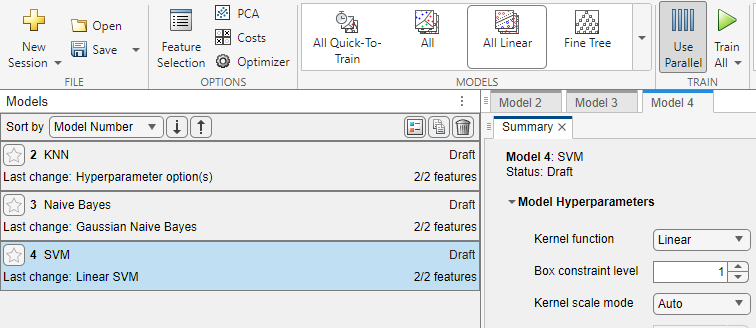

# Funciones

% Sirve para ver qué haría el clasificador en cualquier punto de la gráfica, no solo en los pacientes que existen.
function plot_decision_surface(fig, model, data, resolution, color)
    
    figure(fig)
    
    % Crea una lista de valores de presión sistólica, desde la más baja hasta la más alta, de 0.1 en 0.1. Hace lo mismo con la diastólica.
    x1range = min(data(:,1)):resolution:max(data(:,1));
    x2range = min(data(:,2)):resolution:max(data(:,2));

    % Combina las dos listas para formar una rejilla: miles de puntos repartidos por toda la gráfica. Cada punto es un "paciente inventado".
    [xx1, xx2] = meshgrid(x1range,x2range);
    XGrid = [xx1(:) xx2(:)];
    
    % Pedir al clasificador que clasifique cada paciente inventado
    predictions = predict(model,XGrid);

    % Pintar cada punto de la rejilla de un color según la respuesta: cian si "Smoker" y amarillo si "Non-Smoker".
    gscatter(xx1(:), xx2(:), predictions, color);

end



% Recibe una Matriz de Confusión y devuelve un conjunto de métricas de evaluación
function [Scores] = scores_binary_cm(CM) 

% las filas son la clase real y las columnas la predicha. 
% Smoker es la primera clase y es la positiva

    if size(CM) == [2,2]
        TP = CM(1,1);  FN = CM(1,2);
        FP = CM(2,1);  TN = CM(2,2);
        % las ecuaciones de las métricas Recall, Precision, F1_score y Accuracy
        Recall    = TP / (TP + FN);
        Precision = TP / (TP + FP);
        F1_Score  = 2 * Precision * Recall / (Precision + Recall);
        Accuracy  = (TP + TN) / (TP + TN + FP + FN);
    else
        error('scores_binary_cm:CM', 'la matriz de confusión debe ser 2x2, calisifcador binario.');
    end

    Scores = [Recall' Precision' F1_Score' Accuracy'];
   
end
